%        row, column, frame
N = 1000; % 1,000 sample points
n = 0:N-1;
fc = 10;
fs = 100;
dt = 1/fs;
dh = 100;
c0 = 1200;
G = c0.*dt/dh;
c0 = 1200;
%disp(c0*dt/dh)
nT = n*dt;
fm = 10
% support on [-5,5]
lb = -5;
ub = 5;
% signal time

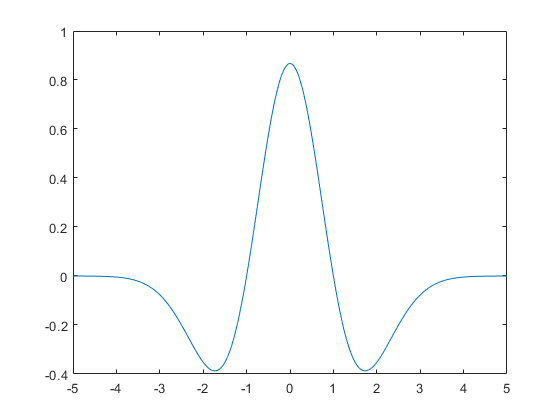

[psi,xval] = mexihat(lb,ub,N);
figure; plot(xval,psi);

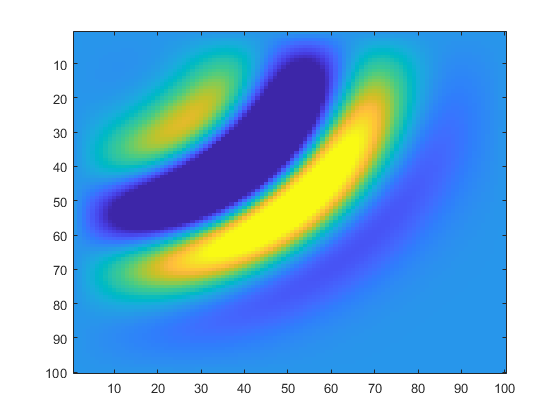

P = zeros(100, 100, N);
figure; 
for idx_time = 2:N-1
    for idx_row = 2:size(P,1)-1
        for idx_column = 2:size(P,2)-1
            if idx_row == 4 && idx_column == 4 
                P(idx_row, idx_column, idx_time + 1) = 2*(1-2*G^2).*P(idx_row, idx_column, idx_time) - P(idx_row, idx_column, idx_time - 1) + G.^2*(P(idx_row + 1, idx_column, idx_time) + P(idx_row - 1, idx_column, idx_time) +  P(idx_row, idx_column + 1, idx_time) + P(idx_row, idx_column - 1, idx_time)) + psi(idx_time);                
            else
                P(idx_row, idx_column, idx_time + 1) = 2*(1-2*G^2).*P(idx_row, idx_column, idx_time) - P(idx_row, idx_column, idx_time - 1) + G.^2*(P(idx_row + 1, idx_column, idx_time) + P(idx_row - 1, idx_column, idx_time) +  P(idx_row, idx_column + 1, idx_time) + P(idx_row, idx_column - 1, idx_time));
            end
        end
    end
    imagesc(P(:,:, idx_time)); caxis([-0.4 0.8]);
    pause(0.1);
end